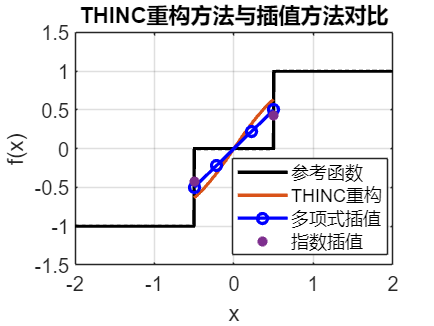

%% THINC重构方法与插值方法对比程序
% 作者: [您的姓名]
% 日期: [日期]
% 描述: 比较THINC重构方法与多项式插值方法在处理分段函数时的效果

clc; clear; close all;

%% 1. 定义参考函数（分段函数）
% 定义计算区间
x_range = linspace(-2, 2, 1000);

% 创建分段函数 f(x)
reference_function = create_piecewise_function(x_range);

%% 2. 绘制参考函数
figure('Name', 'THINC重构方法对比', 'Position', [100, 100, 800, 600]);
plot(x_range, reference_function, 'k', 'LineWidth', 2, 'DisplayName', '参考函数');
hold on;
grid on;

% 设置坐标轴
ylim([-1.5, 1.5]); 
xlim([-2, 2]);
xlabel('x'); 
ylabel('f(x)');
title('THINC重构方法与插值方法对比');

%% 3. 定义重构区间和参数
% 重构区间 [-0.5, 0.5]
xa = -0.5;  % 左边界
xb = 0.5;   % 右边界
x_recon = linspace(xa, xb, 200);  % 重构点

% 单元平均值
u_left   = -1;  % 左邻单元平均值
u_center =  0;  % 当前单元平均值  
u_right  =  1;  % 右邻单元平均值

% THINC参数
beta = 1.5;  % 锐度参数

%% 4. 计算各种重构方法的结果
% THINC重构
y_thinc = compute_thinc_reconstruction(x_recon, xa, xb, u_left, u_center, u_right, beta);

x_recon_gauss = [-1/2 -sqrt(5)/10 sqrt(5)/10 1/2];

% 零阶多项式插值（常数）
y_poly0 = compute_polynomial_interp_0(x_recon_gauss, xa, xb, u_left, u_center);

% 一阶指数插值
lambda = 1;  % 指数参数
y_exp1 = compute_exponential_interp_1(x_recon_gauss, xa, xb, u_left, u_center, lambda);

%% 5. 绘制对比结果
plot(x_recon, y_thinc, 'LineWidth', 2, 'DisplayName', 'THINC重构');
plot(x_recon_gauss, y_poly0, '-ob', 'LineWidth', 2, 'DisplayName', '多项式插值');
plot(x_recon_gauss([1,4]), y_exp1([1,4]), '*', 'LineWidth', 2, 'DisplayName', '指数插值');

% 添加图例和格式化
legend('Location', 'best');
set(gca, 'FontSize', 12);


%% 6. 输出统计信息
fprintf('=== 重构方法对比分析 ===\n');

=== 重构方法对比分析 ===


fprintf('重构区间: [%.1f, %.1f]\n', xa, xb);

重构区间: [-0.5, 0.5]


fprintf('左邻单元值: %.1f\n', u_left);

左邻单元值: -1.0


fprintf('当前单元值: %.1f\n', u_center);

当前单元值: 0.0


fprintf('右邻单元值: %.1f\n', u_right);

右邻单元值: 1.0


fprintf('THINC参数β: %.1f\n', beta);

THINC参数β: 1.5


fprintf('========================\n');


%% ========== 函数定义区域 ==========


function f_values = create_piecewise_function(x)
    %CREATE_PIECEWISE_FUNCTION 创建分段函数
    % 输入:
    %   x - 自变量向量
    % 输出:
    %   f_values - 函数值向量
    %
    % 分段函数定义:
    %   f(x) = -1, x < -0.5
    %   f(x) =  0, -0.5 ≤ x < 0.5  
    %   f(x) =  1, x ≥ 0.5
    
    f_values = zeros(size(x));
    f_values(x < -0.5) = -1;
    f_values(x >= -0.5 & x < 0.5) = 0;
    f_values(x >= 0.5) = 1;
end

function y_values = compute_thinc_reconstruction(x_points, xa, xb, u_left, u_center, u_right, beta)
    %COMPUTE_THINC_RECONSTRUCTION THINC重构方法
    % 输入:
    %   x_points - 重构点坐标
    %   xa, xb   - 单元边界
    %   u_left   - 左邻单元平均值
    %   u_center - 当前单元平均值
    %   u_right  - 右邻单元平均值
    %   beta     - 锐度参数
    % 输出:
    %   y_values - 重构值
    
    y_values = zeros(size(x_points));
    
    for i = 1:length(x_points)
        y_values(i) = thinc_reconstruction_single_point(...
            u_left, u_center, u_right, xa, x_points(i), xb, beta);
    end
end

function val = thinc_reconstruction_single_point(u_left, u_center, u_right, xa, xp, xb, beta)
    %THINC_RECONSTRUCTION_SINGLE_POINT 单点THINC重构
    % 这是THINC (Tangent of Hyperbola for INterface Capturing) 方法的核心算法
    
    % 计算边界值
    Q_min = min(u_left, u_right);
    Q_max = max(u_left, u_right) - Q_min;
    
    % 确定方向
    theta = sign(u_right - u_left);
    
    % 避免除零的小量
    epsilon = 1e-20;
    
    % 计算THINC参数
    C = (u_center - Q_min + epsilon) / (Q_max + epsilon);
    B = exp(theta * beta * (2.0 * C - 1.0));
    
    % 计算特征参数
    xc = (exp(beta) - B) / (B - exp(-beta));
    xcc = log(xc) / (2.0 * beta);
    
    % 归一化坐标
    xi = (xp - xa) / (xb - xa);
    
    % THINC重构公式
    val = 0.5 * Q_max * (1 + theta * tanh(beta * (xi - xcc))) + Q_min;
end

function y_values = compute_polynomial_interp_0(x_points, xa, xb, u_left, u_center)
    %COMPUTE_POLYNOMIAL_INTERP_0 零阶多项式插值（常数插值）
    % 输入:
    %   x_points - 插值点坐标（必须是特定的四个点）
    %   xa, xb   - 单元边界
    %   u_left   - 左邻单元平均值  
    %   u_center - 当前单元平均值
    % 输出:
    %   y_values - 插值结果
    % 
    % 注: 此函数只能对 [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2] 四个点进行插值
    
    % 验证输入点是否正确
    expected_points = [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2];
    if length(x_points) ~= 4 || ~all(abs(x_points - expected_points) < 1e-10)
        error('插值点必须是 [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2]');
    end
    
    % 零阶多项式插值：在整个区间内使用常数值
    y_values = u_center * ones(size(x_points));
    
    y_values(1) = wenoPol3(-1, 0, 1, 0);
    y_values(2) = wenoPol3(-1, 0, 1, 1);
    y_values(3) = wenoPol3(-1, 0, 1, 2);
    y_values(4) = wenoPol3(-1, 0, 1, 3);
end

function y_values = compute_exponential_interp_1(x_points, xa, xb, u_left, u_center, lambda)
    %COMPUTE_EXPONENTIAL_INTERP_1 一阶指数插值
    % 输入:
    %   x_points - 插值点坐标（必须是特定的四个点）
    %   xa, xb   - 单元边界
    %   u_left   - 左邻单元平均值
    %   u_center - 当前单元平均值
    %   lambda   - 指数参数
    % 输出:
    %   y_values - 插值结果
    %
    % 注: 此函数只能对 [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2] 四个点进行插值
    
    % 验证输入点是否正确
    expected_points = [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2];
    if length(x_points) ~= 4 || ~all(abs(x_points - expected_points) < 1e-10)
        error('插值点必须是 [-1/2, -sqrt(5)/10, sqrt(5)/10, 1/2]');
    end
    

    y_values(1) = wenoExp3(-1, 0, 1, 0, lambda);
    y_values(2) = wenoExp3(-1, 0, 1, 0, lambda);
    y_values(3) = wenoExp3(-1, 0, 1, 3, lambda);
    y_values(4) = wenoExp3(-1, 0, 1, 3, lambda);
end